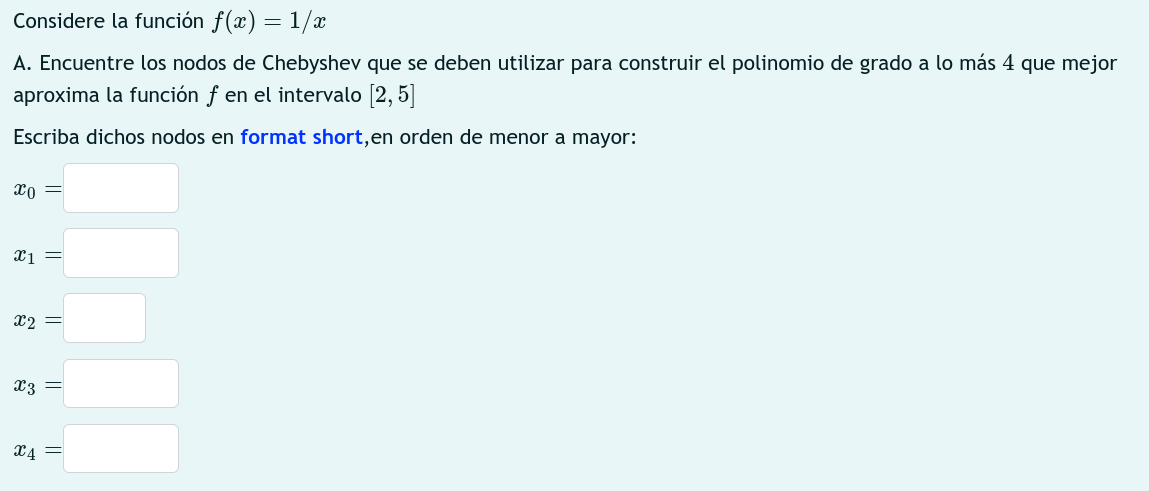

clear
syms f(x)
f(x) = 1/x

$$f(x) = \frac{1}{x}$$


xx = linspace(2,5,5)

xx =     2.0000    2.7500    3.5000    4.2500    5.0000


yy = f(xx)

$$yy = \left(\begin{array}{ccccc} \frac{1}{2} & \frac{4}{11} & \frac{2}{7} & \frac{4}{17} & \frac{1}{5} \end{array}\right)$$



[X, Y] = nodoschebyshev (f, 4, 2, 5)

X =     4.9266    4.3817    3.5000    2.6183    2.0734


$$Y = \left(\begin{array}{ccccc} \frac{70368744177664}{346677583662335} & \frac{562949953421312}{2466665357574265} & \frac{2}{7} & \frac{2251799813685248}{5895937265499677} & \frac{70368744177664}{145903625581313} \end{array}\right)$$

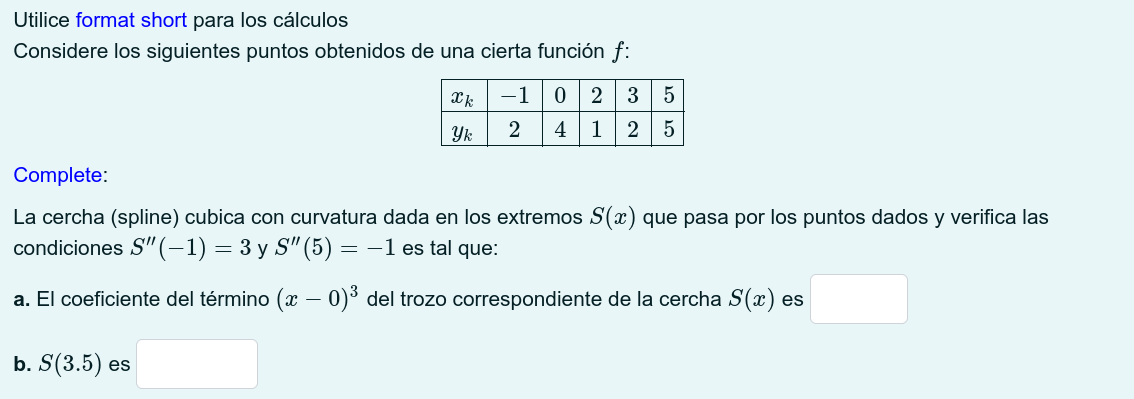

clear
xx = [-1 0 2 3 5]

xx =     -1     0     2     3     5


yy = [2 4 1 2 5]

yy =      2     4     1     2     5



S=csconocido(xx,yy,3,-1)

S =    -1.4050    1.5000    1.9050    2.0000
    0.8100   -2.7151    0.6900    4.0000
   -0.6953    2.1452   -0.4498    1.0000
   -0.0932    0.0591    1.7545    2.0000



f = S(4,:)

f =    -0.0932    0.0591    1.7545    2.0000



polyval(f,3.5-3)

ans = 2.8804

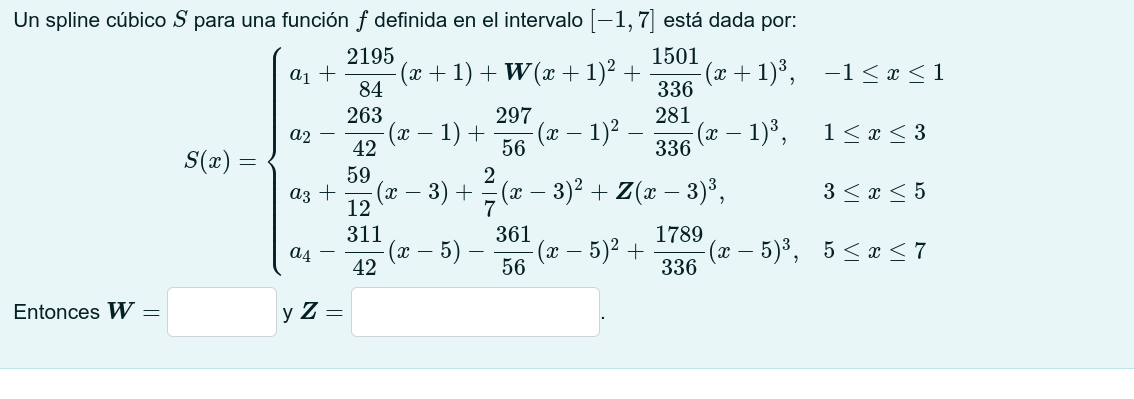

syms f(w) f1(z)
f(w) = 2*w + (2*3*(1501/336)*(2)) == 2*297/56

$$f(w) = 2\,w+\frac{1501}{28}=\frac{297}{28}$$


double(solve(f(w)))

ans = -21.5000


f1(z) = 2*(2/7) + (2*3*z*(2)) == 2*-361/56

$$f1(z) = 12\,z+\frac{4}{7}=-\frac{361}{28}$$


double(solve(f1))

ans = -1.1220

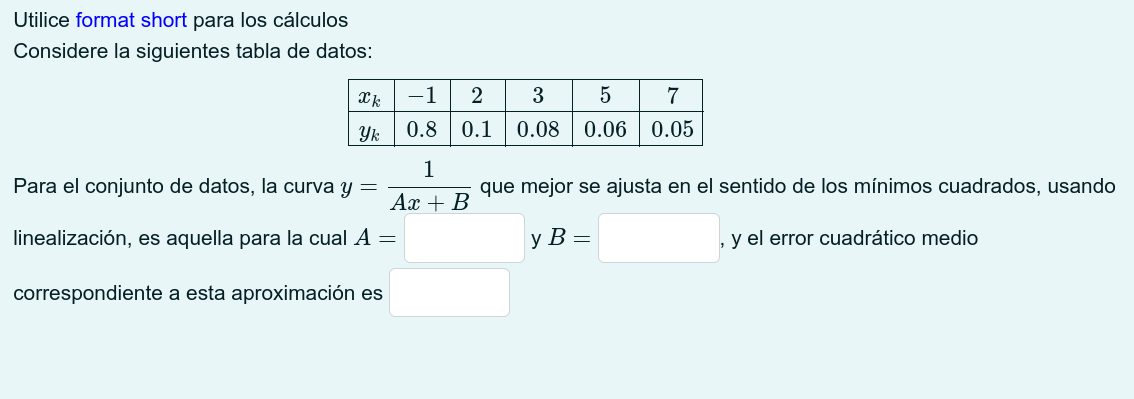

clear
clf
X = [-1 2 3 5 7]

X =     -1     2     3     5     7



yy = [0.8 0.1 0.08 0.06 0.05];

% Se de debe linealizar

Y = 1./yy

Y =     1.2500   10.0000   12.5000   16.6667   20.0000



[A, B] = lsline (X,Y)

A = 2.3438

B = 4.5833


f = @(x) 1./(A*x + B)

f = function_handle with value:
    @(x)1./(A*x+B)


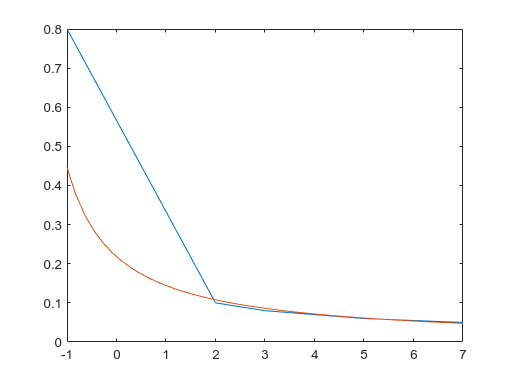


plot(X,yy)
hold on
fplot(f,[-1 7])


ECM = sum((abs(f(X)-yy)).^2)

ECM = 0.1251


ECM = ECM/5

ECM = 0.0250

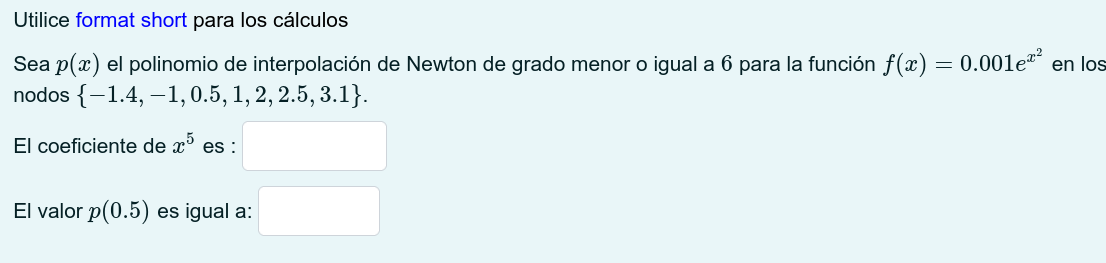

clear
syms f(x)
xx = [-1.4 -1 0.5 1 2 2.5 3.1]

xx =    -1.4000   -1.0000    0.5000    1.0000    2.0000    2.5000    3.1000



f(x) = 0.001*exp(x^2)

$$f(x) = \frac{{\mathrm{e}}^{x^{2}}}{1000}$$


yy = f(xx);
double(yy)

ans =     0.0071    0.0027    0.0013    0.0027    0.0546    0.5180   14.9132





[C, D] = newpoly (xx, yy)

C =     0.1884   -0.6597   -0.1583    2.0562   -0.6633   -1.3966    0.6359


D =     0.0071         0         0         0         0         0         0
    0.0027   -0.0110         0         0         0         0         0
    0.0013   -0.0010    0.0053         0         0         0         0
    0.0027    0.0029    0.0019   -0.0014         0         0         0
    0.0546    0.0519    0.0327    0.0103    0.0034         0         0
    0.5180    0.9268    0.5833    0.2753    0.0757    0.0185         0
   14.9132   23.9919   20.9683    9.7071    3.6276    0.8663    0.1884



%Recordar que los coeficientes van de mayor a menor

polyval(C,0.5)

ans = 0.0013

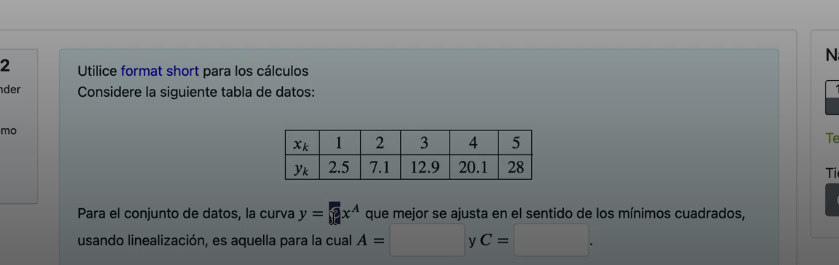

syms f(x) C A


f(x) = C*x^A

$$f(x) = C\,x^{A}$$


log(C*x^A)

$$ans = \log\left(C\,x^{A}\right)$$


log(x^A)

$$ans = \log\left(x^{A}\right)$$